# Team project: Incompressible potential flow around an airfoil

UE 322.061 Num1, SS 2021

created by:

Franz Haller, 01525883

Simon Klocker, ***<XXX***

David Kerekes, 01226653

## 1.    Problem formulation

Cauchy-Riemann equations:

Irrotationality:

$\nabla \times \overrightarrow{u} \equiv \partial_x \;v-\partial_y \;u=0$ (1a)

Incompressibility:

$\nabla \cdot \overrightarrow{u} \equiv \partial_x \;u+\partial_y \;v=0$ (1b)

No-penetration boundary condition:


$$\vec{u} \cdot \overrightarrow{n} =0\;\;\;\;\;\;\;\;\;\mathrm{on}\;\;\;\;\;\;\;\;\Gamma_C \cup \Gamma_F$$


                                                                                           (1c)


$$\;\Gamma_C \;:\sqrt{x^2 +y^2 }=r_c \;,\;\;\;\;\;\;\;\;\;\;\Gamma_F :y=0$$


Far-�field condition:


$$\vec{u} \to \left(1,0\right)\;\;\;\;\;\;\;\mathrm{as}\;\;\;\;\;\;\;x^2 +y^2 \to \infty$$


Approximating the far-fi�eld condition by imposing a Dirichlet BC on the outer boundary:

$\overrightarrow{u} \to \left(1,0\right)\;\;\;\;\;\;\;\mathrm{at}\;\;\;\;\;\;\;\Gamma_O :\sqrt{x^2 +y^2 }=r_o$ (1d)

### 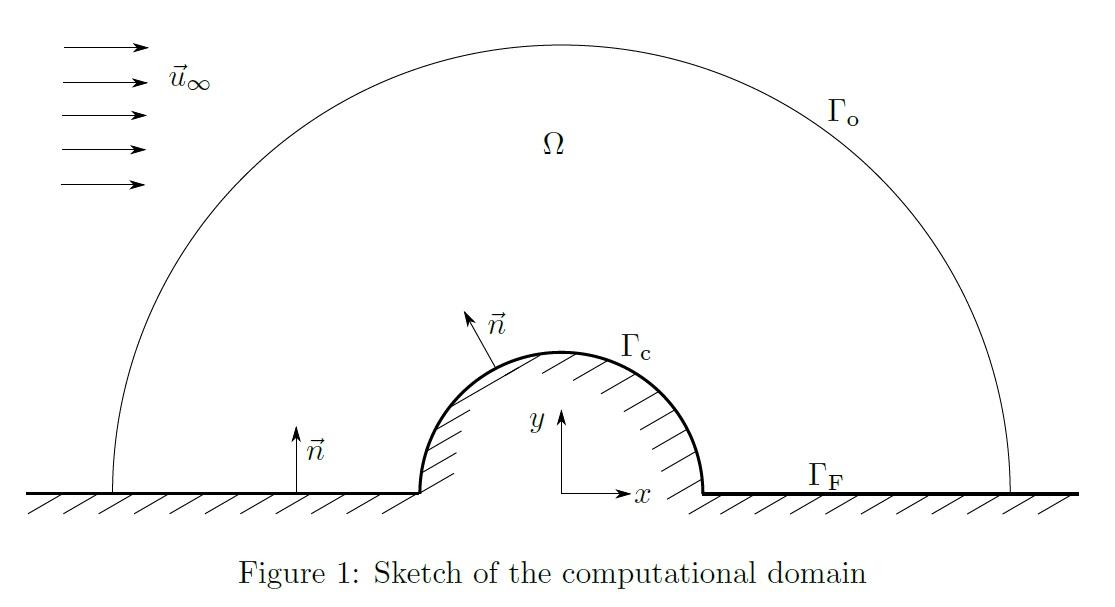

### 1a) Determine the type of the system (1). Comment if and where we have to impose initial and boundary conditions.

To determine the type of a system of first order PDE´s we look at the general form in Matrix-vector notation:


$$\mathbf{A}\partial_{\mathrm{x}\;} \mathbf{u}+\mathbf{B}\partial_{\mathrm{y}} \;\mathbf{u}+\mathbf{Cu}=0$$


Where we can define A, B and C:

clearvars;
close all;

syms dx dy u1 v1;
syms M real;

A = [0,1;
    1,0]

A =      0     1
     1     0



B = [-1,0;
    0,1]

B =     -1     0
     0     1



C = [0,0;
    0,0]

C =      0     0
     0     0


Now we determine the type by solving:


$$\det \left(A^T \textrm{dy}-B^T \textrm{dx}\right)=0$$


determinant = det(A'*dy-B'*dx)

$$determinant = -{\mathrm{dx}}^{2}-{\mathrm{dy}}^{2}$$

solve(determinant == 0 , dx)

$$ans = \left(\begin{array}{c} -\mathrm{dy}\,\mathrm{i}\\ \mathrm{dy}\,\mathrm{i} \end{array}\right)$$

So we get no real solutions for the System. We conclude that the PDE-System is **elliptic.**

Since we have an elliptic equation, boundary conditions must be defined over all boundaries. There is no time-derivative so no initial conditions have to be made.

### 1b)The velocity field satisfying (1) is potential, which means there exists a velocity potential $\phi$ such that

$\vec{u} =\nabla \phi$ (2)

### Show that using (2) the system (1a,1b) reduces to and equivalent Laplace equation

$\nabla^2 \phi =0$ (3)

### 1c) Confirm that the type of (3) is the same as the type of (1)

Rewriting (3):


$$\frac{\partial^2 \phi }{\partial x^2 }+\frac{\partial^2 \phi }{\partial y^2 }=0$$


Comparing with a general linear PDE:


$$\left(A\partial_x^2 +B\partial_{\textrm{xy}} +C\partial_y^2 \right)u\left(x,y\right)=0$$


and the factor


$$s=-\frac{B}{2A}\pm \frac{1}{2A}\sqrt{B^2 -4\textrm{AC}}$$



$$A=1,\;\;B=0,\;\;C=1$$


and

$s=0\pm \frac{1}{2}\sqrt{-4}=\pm \sqrt{-1}$,  a complex value.

The factors of the discriminate:


$$B^2 -4\textrm{AC}=-4\;\;\;<0\;\;\;\;$$


According to (1.24) of the script the type of (3) is **elliptic**, which is the same as of (1).

### 1.d) Confirm that the boundary conditions

$\frac{\partial \phi }{\partial r}=0\;\;\mathrm{at}\;\;\Gamma_C$        $\frac{\partial \phi }{\partial \theta }=0\;\;\mathrm{at}\;\;\Gamma_F$        (4a)

$\phi =x\;\;\;\mathrm{at}\;\;\Gamma_0$                                        (4b)

### are equivalent to (1c,1d)

$\frac{\partial \phi }{\partial r}=0\;\;\mathrm{at}\;\;\Gamma_C$:


$$x:\frac{\partial \phi }{\partial r}=\frac{\partial \phi }{\partial x}\frac{\partial x}{\partial r}=u\frac{\partial }{\partial r}r\;\cos \left(\Theta \right)=u\;\cos \left(\Theta \right)$$



$$y:\frac{\partial \phi }{\partial r}=\frac{\partial \phi }{\partial y}\frac{\partial y}{\partial r}=v\frac{\partial }{\partial r}r\;\sin \left(\Theta \right)=v\;\;\sin \left(\Theta \right)$$


This is equivalent to $\vec{u} \cdot \vec{n}$

$\frac{\partial \phi }{\partial \theta }=0\;\;\textrm{at}\;\;\Gamma_F$:


$$x:\frac{\partial \phi }{\partial \theta }=\frac{\partial \phi }{\partial x}\frac{\partial x}{\partial \theta }=u\frac{\partial }{\partial \theta }r\;\cos \left(\theta \right)=u\;r\;\left(-\sin \left(\theta \right)\right)$$



$$y:\frac{\partial \phi }{\partial \theta }=\frac{\partial \phi }{\partial y}\frac{\partial y}{\partial \theta }=v\frac{\partial }{\partial \theta }r\;\sin \left(\theta \right)=v\;\;r\;\cos \left(\theta \right)$$


This is equivalent to $\vec{u} \cdot \vec{n}$


$$\phi =x\;\;\;\mathrm{at}\;\;\Gamma_0 :$$


means $\frac{\partial \phi }{\partial x}=\frac{\partial x}{\partial x}=1$

with $\vec{u} =\nabla \phi$

leads to $\vec{u} =u\left(1,0\right)$

### 1d)

## 2.    Transformation of coordinates

### We can simplify the mesh generation and implementation of the no-penetration boundary condition by solving (1) in polar coordinates

$\theta =\arctan \left(\frac{y}{x}\right)$        $r=\sqrt{x^2 +y^2 }$        (5a)

$x=r\;\cos \;\theta$            $y=r\;\sin \;\theta$              (5b)

### The transformed computational domain is then given by the rectangle $\Omega =\langle 0,\pi \rangle \times \langle r_c ,r_o \rangle$.

### 2a)Find the Jacobian of the coordinate transformation

$\mathbf{J}=\left\lbrack \begin{array}{cc}
\frac{\partial x}{\partial \theta } & \frac{\partial y}{\partial \theta }\\
\frac{\partial x}{\partial r} & \frac{\partial y}{\partial r}
\end{array}\right\rbrack$ (6)

syms theta r
x=r*cos(theta);
y=r*sin(theta)

$$y = r\,\sin\left(\theta \right)$$

J=[diff(x,theta), diff(y,theta)
    diff(x,r), diff(y,r)]

$$J = \left(\begin{array}{cc} -r\,\sin\left(\theta \right) & r\,\cos\left(\theta \right)\\ \cos\left(\theta \right) & \sin\left(\theta \right) \end{array}\right)$$

### 2.b) Express the inverse transformation of partial derivatives

$\left\lbrack \begin{array}{c}
\frac{\partial }{\partial x}\\
\frac{\partial }{\partial y}
\end{array}\right\rbrack ={\mathbf{J}}^{-1} \left\lbrack \begin{array}{c}
\frac{\partial }{\partial \theta }\\
\frac{\partial }{\partial r}
\end{array}\right\rbrack$ (7)

J_theta_r=simplify(inv(J))

$$J\_theta\_r = \left(\begin{array}{cc} -\frac{\sin\left(\theta \right)}{r} & \cos\left(\theta \right)\\ \frac{\cos\left(\theta \right)}{r} & \sin\left(\theta \right) \end{array}\right)$$

### 2.c) Check that the inverse transformation (7) satisfies the chain rule

$\frac{\partial }{\partial x}=\frac{\partial \theta }{\partial x}\;\frac{\partial }{\partial \theta }+\frac{\partial r}{\partial x}\;\frac{\partial }{\partial r}$ (8a)

$\frac{\partial }{\partial y}=\frac{\partial \theta }{\partial y}\;\frac{\partial }{\partial \theta }+\frac{\partial r}{\partial y}\;\frac{\partial }{\partial r}$ (8b)

Calculated with (7):

d_dx_dy_1=[simplify(diff(J_theta_r(1,1),theta)+diff(J_theta_r(1,2),r))
    simplify(diff(J_theta_r(2,1),theta)+diff(J_theta_r(2,2),r))]

$$d\_dx\_dy\_1 = \left(\begin{array}{c} -\frac{\cos\left(\theta \right)}{r}\\ -\frac{\sin\left(\theta \right)}{r} \end{array}\right)$$

Calculated with the chain rule:

syms theta r x y
theta_1=atan(y/x);
r_1=sqrt(x^2+y^2);

a1=diff(theta_1,x);
a1=subs(a1,x,r*cos(theta));
a1=subs(a1,y,r*sin(theta));
a1=simplify(a1);
a2=diff(r_1,x);
a2=subs(a2,x,r*cos(theta));
a2=subs(a2,y,r*sin(theta));
a2=simplify(a2);

d_dx_2=diff(a1,theta)+diff(a2,r);

b1=diff(theta_1,y);
b1=subs(b1,x,r*cos(theta));
b1=subs(b1,y,r*sin(theta));
b1=simplify(b1);
b2=diff(r_1,y);
b2=subs(b2,x,r*cos(theta));
b2=subs(b2,y,r*sin(theta));
b2=simplify(b2);

d_dy_2=diff(b1,theta)+diff(b2,r);
d_dx_dy_2=[simplify(diff(a1,theta)+diff(a2,r))
   simplify(diff(b1,theta)+diff(b2,r))]

$$d\_dx\_dy\_2 = \left(\begin{array}{c} -\frac{\cos\left(\theta \right)}{r}\\ -\frac{\sin\left(\theta \right)}{r} \end{array}\right)$$

The results are the same:


$$\left\lbrack \begin{array}{c}
\frac{\partial }{\partial x}\\
\frac{\partial }{\partial y}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\frac{\cos \left(\theta \right)}{r}\\
-\frac{\sin \left(\theta \right)}{r}
\end{array}\right\rbrack$$


### 2.d) Find the expressions to compute the Cartesian second partial derivatives $\frac{\partial }{\partial x}\left(\frac{\partial }{\partial x}\right)$and $\frac{\partial }{\partial y}\left(\frac{\partial }{\partial y}\right)$ from the polar partial derivatives $\frac{\partial^2 }{\partial \theta^2 }$, $\frac{\partial^2 }{\partial r^2 }$, $\frac{\partial^2 }{\partial \theta \partial r}$, $\frac{\partial }{\partial \theta }$, $\frac{\partial }{\partial r}$:


$$\frac{\partial }{\partial x}\left(\frac{\partial }{\partial x}\right)=\frac{\partial^2 \theta }{\partial x^2 }\;\frac{\partial^2 }{\partial \theta^2 }+2\;\frac{\partial \theta }{\partial x}\frac{\partial r}{\partial x}\frac{\partial^2 }{\partial \theta \partial r}+\frac{\partial^2 r}{\partial x^2 }\frac{\partial^2 }{\partial r^2 }$$



$$\frac{\partial }{\partial y}\left(\frac{\partial }{\partial y}\right)=\frac{\partial^2 \theta }{\partial y^2 }\;\frac{\partial^2 }{\partial \theta^2 }+2\;\frac{\partial \theta }{\partial y}\frac{\partial r}{\partial y}\frac{\partial^2 }{\partial \theta \partial r}+\frac{\partial^2 r}{\partial y^2 }\frac{\partial^2 }{\partial r^2 }$$


### 2b)

### 2c)

### 2d)

### 2e) Let us introduce a position vector in cartesian coordinates. Express the polar basis vectors.


$$\overrightarrow{x} =\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
r\;\cos \left(\theta \right)\\
r\;\sin \left(\theta \right)
\end{array}\right\rbrack$$


For the polar basis vectors we define:

${\overrightarrow{e} }_r =\frac{\partial \overrightarrow{x} }{\partial r}/{\left\|\frac{\partial \overrightarrow{x} }{\partial r}\right\|}_2$  ,  ${\overrightarrow{e} }_{\Theta } =\frac{\partial \overrightarrow{x} }{\partial \Theta }/{\left\|\frac{\partial \overrightarrow{x} }{\partial \Theta }\right\|}_2$

clear all
syms r theta x F_x F_y delta_x delta_y e_x e_y;

%x = r*cos(theta);
%y = r*sin(theta);
x_vec = [r*cos(theta),r*sin(theta)];

e_r = diff(x_vec,r)/norm(diff(x_vec,r))

$$e\_r = \left(\begin{array}{cc} \frac{\cos\left(\theta \right)}{\sqrt{{\left|\cos\left(\theta \right)\right|}^{2}+{\left|\sin\left(\theta \right)\right|}^{2}}} & \frac{\sin\left(\theta \right)}{\sqrt{{\left|\cos\left(\theta \right)\right|}^{2}+{\left|\sin\left(\theta \right)\right|}^{2}}} \end{array}\right)$$


e_theta = diff(x_vec,theta)/norm(diff(x_vec,theta))

$$e\_theta = \left(\begin{array}{cc} -\frac{r\,\sin\left(\theta \right)}{\sqrt{{\left|r\,\cos\left(\theta \right)\right|}^{2}+{\left|r\,\sin\left(\theta \right)\right|}^{2}}} & \frac{r\,\cos\left(\theta \right)}{\sqrt{{\left|r\,\cos\left(\theta \right)\right|}^{2}+{\left|r\,\sin\left(\theta \right)\right|}^{2}}} \end{array}\right)$$

%x = r*cos(theta);
%y = r*sin(theta);

and so we get:


$${\overrightarrow{e} }_r =\cos \left(\theta \right)\;{\overrightarrow{e} }_x +\sin \left(\theta \right)\;{\overrightarrow{e} }_y$$
 

 
$${\overrightarrow{e} }_{\theta } =-\sin \left(\theta \right)\;{\overrightarrow{e} }_x +\cos \left(\theta \right)\;{\overrightarrow{e} }_y$$


#### 2f) Invert the system and express ${\overrightarrow{e} }_x$ and ${\overrightarrow{e} }_y$ in terms of  ${\overrightarrow{e} }_r$ and ${\overrightarrow{e} }_{\Theta }$

For this task, we define a Transformation-Matrix T:

T = [cos(theta)  sin(theta)
    -sin(theta) cos(theta)]

$$T = \left(\begin{array}{cc} \cos\left(\theta \right) & \sin\left(\theta \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

inverting the System we get:

simplify(inv(T))

$$ans = \left(\begin{array}{cc} \cos\left(\theta \right) & -\sin\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

Therefore for ${\overrightarrow{e} }_x$ and ${\overrightarrow{e} }_y$:


$${\overrightarrow{e} }_x =\cos \left(\Theta \right)\;{\overrightarrow{e} }_r -\sin \left(\Theta \right)\;{\overrightarrow{e} }_{\Theta }$$
 

 
$${\overrightarrow{e} }_y =\sin \left(\Theta \right)\;{\overrightarrow{e} }_r +\cos \left(\Theta \right)\;{\overrightarrow{e} }_{\Theta }$$


#### 2g) Using the result of the previous question, show that the transformation of vectors from Cartesian to Polar basis reads:


$$\overrightarrow{F} ={\mathrm{F}}_x \;\;{\overrightarrow{e} }_x +{\mathrm{F}}_x \;\;{\overrightarrow{e} }_y =\left({\mathrm{F}}_x \;\cos \left(\Theta \right)+{\mathrm{F}}_y \;\sin \left(\Theta \right)\right){\overrightarrow{e} }_r +\left({-\mathrm{F}}_x \;\sin \left(\Theta \right)+{\mathrm{F}}_y \;\cos \left(\Theta \right)\right){\overrightarrow{e} }_{\Theta }$$


To achieve that, we can Multiply the F-Vector with our Transformation-Matrix:

F_cart = [F_x; F_y];
F_pol = T * F_cart

$$F\_pol = \left(\begin{array}{c} F_{x}\,\cos\left(\theta \right)+F_{y}\,\sin\left(\theta \right)\\ F_{y}\,\cos\left(\theta \right)-F_{x}\,\sin\left(\theta \right) \end{array}\right)$$

so we get:


$$\overrightarrow{F} =\left({\mathrm{F}}_x \;\cos \left(\Theta \right)+{\mathrm{F}}_y \;\sin \left(\Theta \right)\right){\overrightarrow{e} }_r +\left({-\mathrm{F}}_x \;\sin \left(\Theta \right)+{\mathrm{F}}_y \;\cos \left(\Theta \right)\right){\overrightarrow{e} }_{\Theta }$$


#### 2h) Using the results of the previous questions, show that the gradient in polar coordinates reads:


$$\nabla ={\overrightarrow{e} }_r \partial_r +{\overrightarrow{e} }_{\Theta } \frac{1}{r}\partial_{\Theta }$$


The Matrix  with the partial differentials for x and y (Jacobi Matrix) reads:

J = [diff(x_vec(1),r) diff(x_vec(1),theta)
    diff(x_vec(2),r) diff(x_vec(2),theta)]

$$J = \left(\begin{array}{cc} \cos\left(\theta \right) & -r\,\sin\left(\theta \right)\\ \sin\left(\theta \right) & r\,\cos\left(\theta \right) \end{array}\right)$$

e_cart = [e_x; e_y]

$$e\_cart = \left(\begin{array}{c} e_{x}\\ e_{y} \end{array}\right)$$


grad_pol = simplify(J^-1*e_cart)

$$grad\_pol = \left(\begin{array}{c} e_{x}\,\cos\left(\theta \right)+e_{y}\,\sin\left(\theta \right)\\ \frac{e_{y}\,\cos\left(\theta \right)-e_{x}\,\sin\left(\theta \right)}{r} \end{array}\right)$$

so we see  with 2e)


$${\overrightarrow{e} }_r =\cos \left(\Theta \right)\;{\overrightarrow{e} }_x +\sin \left(\Theta \right)\;{\overrightarrow{e} }_y$$
 

 
$${\overrightarrow{e} }_{\Theta } =-\sin \left(\Theta \right)\;{\overrightarrow{e} }_x +\cos \left(\Theta \right)\;{\overrightarrow{e} }_y$$


that the gradient in polar coordinates reads:


$$\nabla ={\overrightarrow{e} }_r \partial_r +{\overrightarrow{e} }_{\Theta } \frac{1}{r}\partial_{\Theta }$$


### 2i)

### 2j)

## 3.    Discretization

### 3a)

### 3b)

### 3c)

### 3d)

### 3e)

### 3f)

## 4.    Computation of the velocity fi�eld

### 4a)

### 4b)

### 4c)

## 5.    Pressure force

### 5a)

### 5b)

### 5c)

### 5d)

## 6.    Streamlines

### 6a)

### 6b)

### 6c)

## 7.    Other graphs

### 7a)

### 7b)